# Figure S2D S2E

### Load Data

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';
load([dataDir filesep 'A039_data.mat'],'S','settings','allIF');

conditions = settings.conditions;


framesPerHr = 60/12;
 frameDrugAdded =0;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;



times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};
% 
for i = 1:length(S)
    S(i).frameDrugAdded = conditions{i,5};
    S(i).POI_realtime = S(i).POI/framesPerHr;
 
   S(i).drug_time = S(i).frameDrugAdded/framesPerHr;
end

 drug_time = frameDrugAdded/framesPerHr;

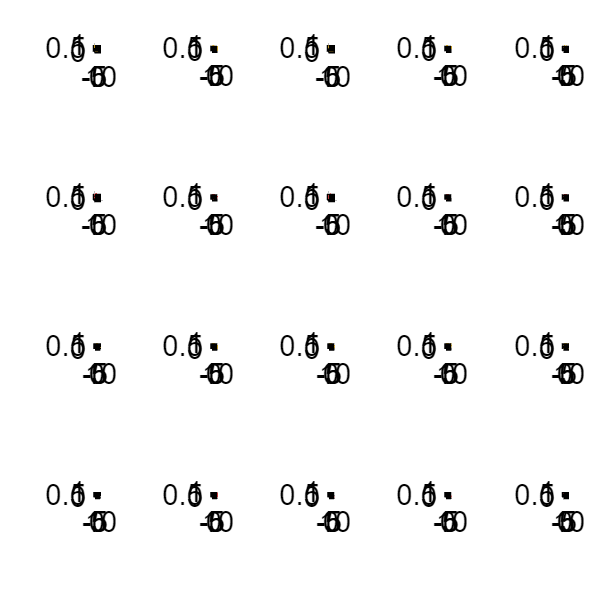

%cells were randomly selected
conds = [6];

     f1 = figure('units','inches','position',[0 0 16 16]);
      

tiledlayout (4,5,'padding','compact','tilespacing','compact')

    numcell = [7705, 4629, 4920, 11847, 1540]; 

    for i = 1:length(numcell)
 
        nexttile(i);
 timeAligned = xTime-S(conds(1)).POI(numcell(i),1)/framesPerHr;
 time2 = xTime-S(conds(1)).POI(numcell,2)/framesPerHr;

 

      axis square
      hold on
    plot(timeAligned,S(conds(1)).sigNorm(numcell(i),:)','Color',[1 .8 .2])
     vline([0],'k--')
      vline(timeAligned(S(conds(1)).POI(numcell(i),2)),'black--');
    ylabel('DBF4-mVenus Intensity','FontSize',14);
     xlabel('Time since mitosis (h)','FontSize',14);
     xlim([-5 10])
     ylim([0 1])
    
     hold off

     nexttile(i+5)
   
  axis square
hold on
  plot(timeAligned,(S(conds(1)).apcNorm(numcell(i),:))','Color',[1 .3 .3])
  vline([0],'k--')
 vline(timeAligned(S(conds(1)).POI(numcell(i),2)),'black--')
    ylabel('APC Reporter Activity','FontSize',14)
    xlabel('Time since mitosis (h)','FontSize',14)
    xlim([-5  10])
    ylim([0 1])
      
  hold off
  
    end


conds = [14];
numcell = [605, 796, 2227,3050, 601];
 for i = 1:length(numcell)
 
        nexttile(i+10);
 timeAligned = xTime-S(conds(1)).POI(numcell(i),1)/framesPerHr;
 time2 = xTime-S(conds(1)).POI(numcell,2)/framesPerHr;
 

      axis square
      hold on
    plot(timeAligned,S(conds(1)).sigNorm(numcell(i),:)','Color',[1 .8 .2])
     vline([0],'k--')
      vline(timeAligned(S(conds(1)).POI(numcell(i),2)),'black--');
    ylabel('Gem-mVenus Intensity','FontSize',14);
     xlabel('Time since mitosis (h)','FontSize',14);
     xlim([-5 10])
     ylim([0 1])
    
     hold off

     nexttile(i+15)
   
  axis square
hold on
  plot(timeAligned,(S(conds(1)).apcNorm(numcell(i),:))','Color',[1 .3 .3])
  vline([0],'k--')
 vline(timeAligned(S(conds(1)).POI(numcell(i),2)),'black--')
    ylabel('APC Reporter Activity','FontSize',14)
    xlabel('Time since mitosis (h)','FontSize',14)
    xlim([-5  10])
    ylim([0 1])
     
  hold off
  
    end

 % print_pdf(['fig_S2D_E.pdf'])